clear, clc, close all

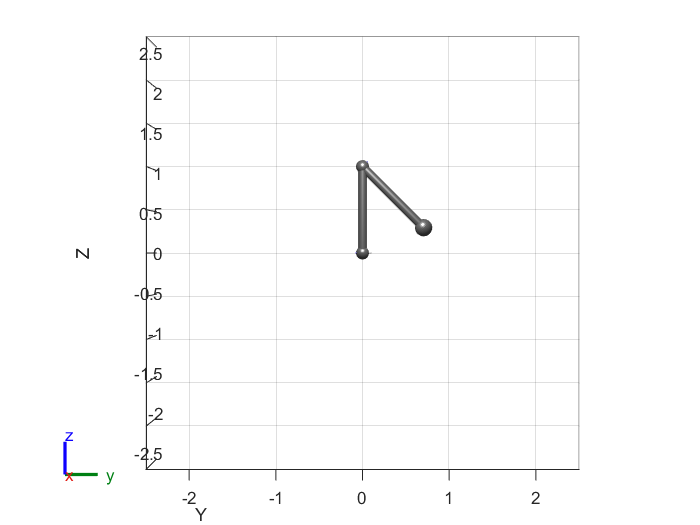

% Create robot
robot = create_robot_tree(1);
robot.Gravity = [0 0 -9.81];
figure
config = homeConfiguration(robot);
pose = [pi/2; -3*pi/4];
figure
show(robot,pose);
xlim([-.01,.1])
view(90,0)

nJoints = 2;
% gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);
m1 = 1;
m2 = 1;
m3 = 1;
L1 = 1;
L2 = 1;
l1 = 0.5;
l2 = 0.5;
g = 9.81;

robot.Bodies{1}.Mass = m1;
robot.Bodies{2}.Mass = m2;
robot.Bodies{3}.Mass = m3;

% I1 = (1/12)*m1*L1^2;
% I2 = (1/12)*m2*L2^2;
I1 = 1;
I2 = 1;
robot.Bodies{1}.Inertia = [I1 0 0 0 0 0];
robot.Bodies{2}.Inertia = [I2 0 0 0 0 0];
robot.Bodies{3}.Inertia = [0 0 0 0 0 0];

% Test simulation of nonlinear robot dynamics
u_test = @(t) [0;0];
t_free_sim = [0,5];
x0 = [pose;zeros(nJoints,1)];
% [t_test,x_test] = sim_robot(robot,u_test,x0,t_free_sim);
% plot_traj(t_test,x_test,nJoints,"Free Test")
% animate_traj2gif(robot,x_test(:,1:2)',0.01,'free_sim.gif')

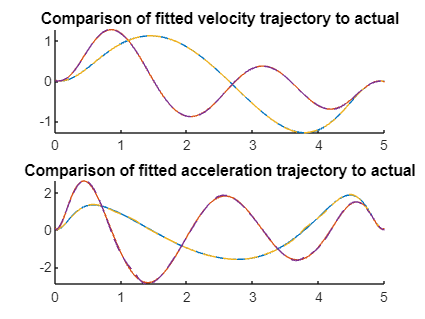

% Create trajectory
ik = inverseKinematics('RigidBodyTree',robot);
% ignore orientation for now
weights = [0 0 0 1 1 1];

% Create waypoints:
xi = [0 1 0.5];
xw = [0 0 1.75];
xf = [0 -1 1];
xw2 = [0 0 1.5];
x = [xi; xw; xf; xw2; xi;];

% Equally spaced time points for each waypoint, can change this
t_fin = 5;
n = size(x,1);
tpts = linspace(0,t_fin,n);

% Timing parameter
r = .01; % This affects how many discrete points there are in the 
% trajectory, and is the main driver of error in the inverse dynamics
% controller below

% Solve for cubic trajectory
% [qt, qtd, qtdd, tpp] = create_cubic_traj(robot,weights,x,tpts,r,pose);

% Solve for minimum jerk trajectory
[qt,qtd,qtdd,qtddd,tpp,tPoints,tSamples] = create_minjerk_traj(robot,weights,x,tpts,r,pose);

% Actually going to be interested in piecewise polynomial tpp, 
% which can be evaluated at an arbitrary time

% Also need velocity of the trajectory as a function of time
order = 12; % Is 10 good enough?
qdp1 = polyfit(tSamples,qtd(1,:),order); 
qdp2 = polyfit(tSamples,qtd(2,:),order);
qddp1 = polyfit(tSamples,qtdd(1,:),order);
qddp2 = polyfit(tSamples,qtdd(2,:),order);
% Compare true to fitted graphically
figure()
subplot(2,1,1)
hold on
title("Comparison of fitted velocity trajectory to actual")
plot(tSamples,polyval(qdp1,tSamples))
plot(tSamples,polyval(qdp2,tSamples))
plot(tSamples,qtd,'--')
subplot(2,1,2)
hold on
title("Comparison of fitted acceleration trajectory to actual")
plot(tSamples,polyval(qddp1,tSamples))
plot(tSamples,polyval(qddp2,tSamples))
plot(tSamples,qtdd,'--')

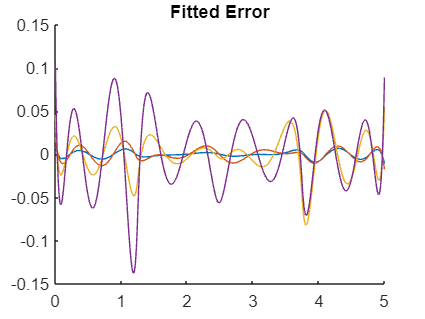


figure()
hold on
title("Fitted Error")
plot(tSamples,[polyval(qdp1,tSamples);polyval(qdp2,tSamples)]-qtd)
plot(tSamples,[polyval(qddp1,tSamples);polyval(qddp2,tSamples)]-qtdd)


% Animate Trajectory
% animate_traj(robot,qt,r) % Need to manually stop execution
% animate_traj2gif(robot,qt,1/10,'true_traj.gif')
ip = 5;
Xs = zeros(size(tSamples(1:ip:end)));
Y1s = L1*cos(qt(1,1:ip:end));
Y2s = Y1s+L2*cos(qt(1,1:ip:end)+qt(2,1:ip:end));
Z1s = L1*sin(qt(1,1:ip:end));
Z2s = Z1s+L2*sin(qt(1,1:ip:end)+qt(2,1:ip:end));

figure
show(robot,qt(:,1))

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
show(robot,qt(:,end/2))

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


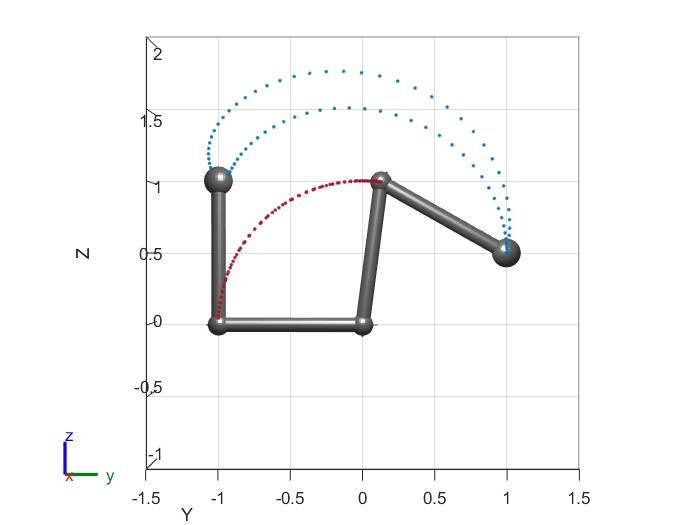

% show(robot,qt(:,end))
plot3(tSamples(1:ip:end)/t_fin*.1,Y1s,Z1s,'.')
plot3(tSamples(1:ip:end)/t_fin*.1,Y2s,Z2s,'.')
xlim([-.01,.1])
ylim([-1.5,1.5])
zlim([-1,2])
view(90,0)

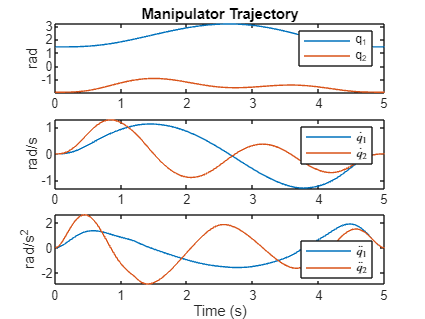

% Plot trajectory
n_traj = size(qt,2);
xt = linspace(0,t_fin,n_traj);
figure
subplot(3,1,1)
plot(xt,qt)
ylabel("rad")
legend("q_1","q_2",'Location','northeast')
title("Manipulator Trajectory")
subplot(3,1,2)
plot(xt,qtd)
legend("$\dot{q}_1$","$\dot{q}_2$",'Location','northeast', 'interpreter', 'latex')
ylabel("rad/s")
subplot(3,1,3)
plot(xt,qtdd)
legend("$\ddot{q}_1$","$\ddot{q}_2$",'Location','southeast', 'interpreter', 'latex')
ylabel("rad/s^2")
xlabel("Time (s)")

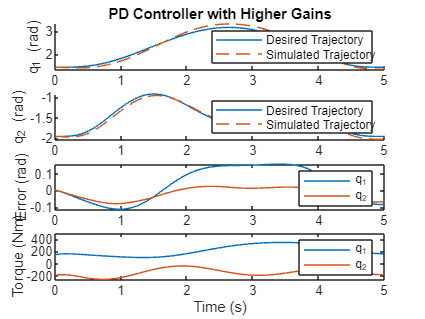


% Test for the robot
q_traj = @(t) [ppval(tpp,t); polyval(qdp1,t); polyval(qdp2,t)]; % Disregard accel.
q_traj_full = @(t) [ppval(tpp,t); polyval(qdp1,t); polyval(qdp2,t); polyval(qddp1,t); polyval(qddp2,t)];

x0 = [qt(:,1);0;0]; % No starting position error

% Also test a PD controller
Kp = 200*eye(nJoints);
Kd = 100*eye(nJoints);
[t_PD,x_PD] = sim_robot_PD(robot,Kp,Kd,q_traj,x0,[0,t_fin]);
q_sim_PD = x_PD(:,1:nJoints)';

tau_pd = zeros(length(t_PD),nJoints);
q_pd_e = zeros(length(t_PD),nJoints);
for i=1:length(t_PD)
    ti = t_PD(i);
    q_traj_t = q_traj(ti);
    qd = q_traj_t(1:nJoints);
    qd_dot = q_traj_t(nJoints+1:2*nJoints);
    tau_pdi = -Kp*(x_PD(i,1:nJoints)'-qd) - Kd*(x_PD(i,nJoints+1:end)'-qd);
    tau_pd(i,:) = tau_pdi;
    q_pd_e(i,:) = x_PD(i,1:nJoints)'-qd;
end
% Plot trajectory from controller vs. true desired trajecory
figure
subplot(4,1,1)
hold on
plot(tSamples,qt(1,:))
plot(t_PD,q_sim_PD(1,:),'--')
legend("Desired Trajectory","Simulated Trajectory",'Location','northeast')
ylabel("q_1 (rad)")
title("PD Controller with Higher Gains")
subplot(4,1,2)
hold on
plot(tSamples,qt(2,:))
plot(t_PD,q_sim_PD(2,:),'--')
legend("Desired Trajectory","Simulated Trajectory",'Location','northeast')
ylabel("q_2 (rad)")
subplot(4,1,3)
plot(t_PD,q_pd_e)
legend("q_1","q_2",'Location','northeast')
ylabel("Error (rad)")
subplot(4,1,4)
plot(t_PD,tau_pd)
legend("q_1","q_2",'Location','southeast')
ylabel("Torque (Nm)")
xlabel("Time (s)")

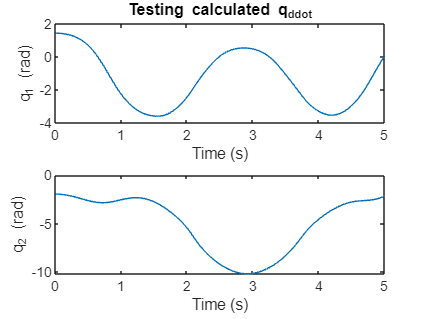

% Get equations of motion from Euler-Langrangian EOMs
[tau, q_ddot_eqn, q_ddot, q_dot, q, u, vars] = robot_arm_dynamics2();
% Set parameters
params = [m1 m2 m3 L1 L2 l1 l2 g];

q_ddot_sub = subs(q_ddot_eqn,vars,params);
eval_vars = formula([q;q_dot;u]);
[t_test2,x_test2] = sim_robot_test(q_ddot_sub,eval_vars,u_test,x0,t_free_sim);
plot_traj(t_test2,x_test2,nJoints,"Testing calculated q_ddot")

% plot_traj(t_test,x_test,nJoints,"Free Sim")
% animate_traj(robot,x_test2(:,1:2)',r)

% Lyapunov function: V = 1/2*(s'*H*s + a_tilde'*inv(eta)*a_tilde)
% V_dot = s'*(tau - H*q_ddot_r - C*q_dot_r - g) + a_hat_dot'*inv(eta)*a_tilde
% tau = Y*a_hat-K_D*s
% a_hat_dot = -eta*Y'*s

% Now rearrange terms according to knowledge of manipulator equation
% structure: tau = H(q)*q_ddot + C(q,q_dot)*q_dot + g(q) = Y*a
% Return terms as Y matrix to be used in adaptive control

% First substitute in known terms:
known = logical([0 0 0 1 0 1 0 1]);
known_params = params(known);
known_vars = vars(known);
unknown_vars = vars(~known);
tau_k = subs(tau,known_vars,known_params);
symvar(tau_k)

$$ans = \left(\begin{array}{cccccc} L_{2} & l_{2} & m_{1} & m_{2} & m_{3} & t \end{array}\right)$$


[Y,a_true,qrs] = collect_manipulator_terms(tau_k, q_ddot, q_dot, q, unknown_vars);
% Find true a
n_a = length(a_true);
a_nums = double(subs(symmatrix2sym(a_true),vars,params));

% Create cyclical trajectory
n_cycles = 1;
tc_fin = t_fin*n_cycles;
q_cycle_full = @(t) q_traj_full(mod(t,t_fin));

% Run trajectory simulation
t_span = [0 tc_fin];
a0 = zeros(length(a_true),1);
xa0 = [x0-0.1; a0];
gamma = diag([5 .05 .05 2 .25 .05]);
% gamma = .05*eye(length(a_nums));
lambda = 10*eye(nJoints);
Kd = 30*eye(nJoints);
Y_vars = [formula(q);formula(q_dot);qrs];
Y2 = symmatrix2sym(Y);
opts = odeset('RelTol',1e-4,'AbsTol',1e-6);
% [t_a,x_a] = ode45(@(t,x) sim_robot_adaptive(t,x,gamma,Kd,lambda,q_cycle_full,Y2,Y_vars,robot),t_span,xa0,opts);
[t_a,x_a] = ode45(@(t,x) sim_robot_adaptive2(t,x,gamma,Kd,lambda,q_cycle_full,Y2,Y_vars,q_ddot_sub,eval_vars),t_span,xa0,opts);

% Backcalculate torques and s errors
q_desired = q_cycle_full(t_a');
tau_a = zeros(length(t_a),nJoints);
s_a = zeros(length(t_a),nJoints);
for i=1:length(t_a)
    ti = t_a(i);
    q_traj_t = q_cycle_full(ti);
    qd = q_traj_t(1:nJoints);
    qd_dot = q_traj_t(nJoints+1:2*nJoints);
    qd_ddot = q_traj_t(2*nJoints+1:end);
    q_tilda = (x_a(i,1:2)-q_desired(1:2,i)')';
    q_tilda_dot = (x_a(i,3:4)-q_desired(3:4,i)')';
    s = q_tilda_dot + lambda*q_tilda;
    qr_dot = qd_dot - lambda*q_tilda;
    qr_ddot = qd_ddot - lambda*q_tilda_dot;
    a_hat = x_a(i,2*nJoints+1:end)';
    new_vars = [x_a(i,1:2)';x_a(i,3:4)';qr_dot;qr_ddot];
    Yt = double(subs(Y2,Y_vars,new_vars));
    tau_ai = Yt*a_hat - Kd*s;
    tau_a(i,:) = tau_ai;
    s_a(i,:) = s;
end

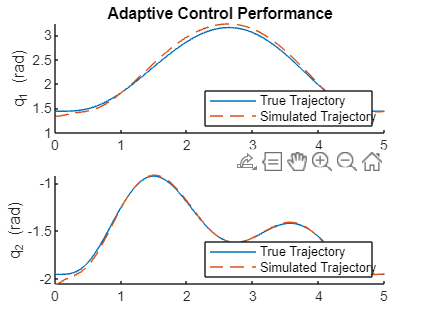

% Plot trajectory from controller vs. true desired trajecory
q_desired = q_cycle_full(t_a');
figure()
subplot(2,1,1)
hold on
plot(t_a,q_desired(1,:))
plot(t_a,x_a(:,1),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
ylabel("q_1 (rad)")
title("Adaptive Control Performance")
subplot(2,1,2)
hold on
plot(t_a,q_desired(2,:))
plot(t_a,x_a(:,2),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
ylabel("q_2 (rad)")

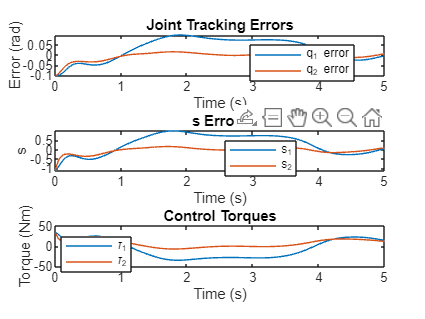


% Plot joint errors, s errors, and control torques
figure()
subplot(3,1,1)
plot(t_a,x_a(:,1:2)-q_desired(1:2,:)')
legend("q_1 error","q_2 error","Location","best")
ylabel("Error (rad)")
xlabel("Time (s)")
title("Joint Tracking Errors")
subplot(3,1,2)
plot(t_a,s_a)
legend("s_1","s_2","Location","best")
ylabel("s")
xlabel("Time (s)")
title("s Errors")
subplot(3,1,3)
plot(t_a,tau_a)
legend("\tau_1","\tau_2","Location","best")
ylabel("Torque (Nm)")
xlabel("Time (s)")
title("Control Torques")

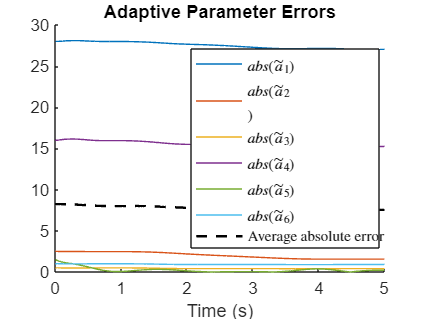


% Plot adaptive parameter errors
a_hats = x_a(:,2*nJoints+1:end);
figure()
hold on
plot(t_a,abs(a_hats-a_nums'))
plot(t_a,mean(abs(a_hats-a_nums'),2),'k--','LineWidth',1.5)
% legend("$$\tilde{a}_1$$","$$\tilde{a}_2$$","$$\tilde{a}_3$$","Average absolute error","Location","best","interpreter","latex")
legend("$$abs(\tilde{a}_1)$$","$$abs(\tilde{a}_2$$)","$$abs(\tilde{a}_3)$$","$$abs(\tilde{a}_4)$$","$$abs(\tilde{a}_5)$$","$$abs(\tilde{a}_6)$$","Average absolute error","Location","best","interpreter","latex")
title("Adaptive Parameter Errors")
xlabel("Time (s)")

% Now assume there is additionally bounded noise w in the mechanical system
% tau + w = H(q)*q_ddot + C(q,q_dot)*q_dot + g(q)
% Use a continuous approximation of sliding controller
% s_d = s - phi*sat(s/phi)

% Want to satisfy sliding condition 1/2*d/dt(s_d^2) <= -n*|s_d|

% V = 1/2*(s_d'*H*s_d + a_tilde'*inv(eta)*a_tilde)
% V_dot = s_d'*(tau - H*q_ddot_r - C*q_dot_r - g - w) + a_hat_dot'*inv(eta)*a_tilde
% with:
% tau = Y*a_hat-k*sat(s/phi), k_i >= |w_i| + n_i
% a_hat_dot = -eta*Y'*s_d
% We get:
% V_dot = -s_d'*k*sat(s/phi) - s_d'*w == -k*|s_d|) - s_d'*w <= -sum(n_i*|s_d_i|)

% Run trajectory simulation
t_span = [0 tc_fin];
sigma = 1;
mu = -sigma/2;
w = @(t) mu + rand(nJoints,1)*sigma; % |w| <= sigma/2
W = -mu + sigma;
a0 = zeros(length(a_true),1);
xa0 = [x0-0.1; a0];
% gamma = diag([2 2 .5 1 1]);
gamma = 0.05*eye(length(a_nums));
lambda = 10*eye(nJoints);
phi = 1/10;
eta = 10;
Y_vars = [formula(q);formula(q_dot);qrs];
Y2 = symmatrix2sym(Y);
opts = odeset('RelTol',1e-2,'AbsTol',1e-4);
% [t_ar,x_ar] = ode45(@(t,x) sim_robot_robust_adaptive(t,x,gamma,phi,lambda,w,W,eta,q_cycle_full,Y2,Y_vars,robot),t_span,xa0,opts);
[t_ar,x_ar] = ode45(@(t,x) sim_robot_robust_adaptive2(t,x,gamma,phi,lambda,w,W,eta,q_cycle_full,Y2,Y_vars,q_ddot_sub,eval_vars),t_span,xa0,opts);

% Backcalculate torques and s errors
q_desired = q_cycle_full(t_ar');
tau_ar = zeros(length(t_ar),nJoints);
s_ar = zeros(length(t_ar),nJoints);
k = W*ones(nJoints,1) + eta;
for i=1:length(t_ar)
    ti = t_ar(i);
    q_traj_t = q_cycle_full(ti);
    qd = q_traj_t(1:nJoints);
    qd_dot = q_traj_t(nJoints+1:2*nJoints);
    qd_ddot = q_traj_t(2*nJoints+1:end);
    q_tilda = (x_ar(i,1:2)-q_desired(1:2,i)')';
    q_tilda_dot = (x_ar(i,3:4)-q_desired(3:4,i)')';
    s = q_tilda_dot + lambda*q_tilda;
    qr_dot = qd_dot - lambda*q_tilda;
    qr_ddot = qd_ddot - lambda*q_tilda_dot;
    a_hat = x_ar(i,2*nJoints+1:end)';
    new_vars = [x_ar(i,1:2)';x_ar(i,3:4)';qr_dot;qr_ddot];
    Yt = double(subs(Y2,Y_vars,new_vars));
    tau_ari = Yt*a_hat - k.*sat(s/phi);
    tau_ar(i,:) = tau_ari;
    s_ar(i,:) = s;
end

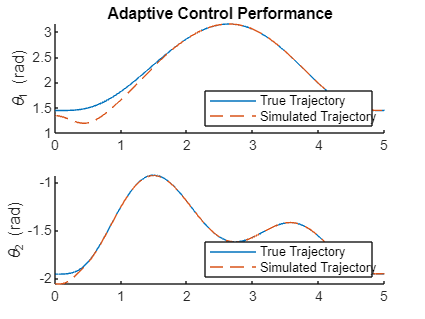

% Plot trajectory from controller vs. true desired trajecory
q_desired = q_cycle_full(t_ar');
figure()
subplot(2,1,1)
hold on
plot(t_ar,q_desired(1,:))
plot(t_ar,x_ar(:,1),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
ylabel("\theta_1 (rad)")
title("Adaptive Control Performance")
subplot(2,1,2)
hold on
plot(t_ar,q_desired(2,:))
plot(t_ar,x_ar(:,2),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
ylabel("\theta_2 (rad)")

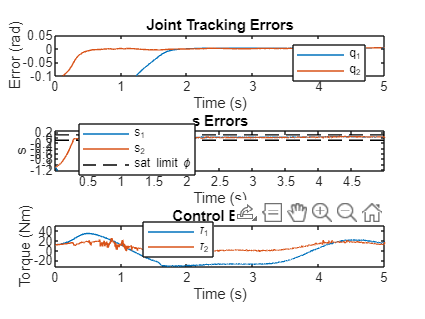


figure()
subplot(3,1,1)
plot(t_ar,x_ar(:,1:2)-q_desired(1:2,:)')
legend("q_1","q_2","Location","best")
ylabel("Error (rad)")
xlabel("Time (s)")
ylim([-.1,.05])
title("Joint Tracking Errors")
subplot(3,1,2)
plot(t_ar,s_ar)
hold on
plot([0 tc_fin],[phi phi],'k--')
plot([0 tc_fin],[-phi -phi],'k--')
legend("s_1","s_2","sat limit \phi","Location","best")
ylabel("s")
ylim([-1 0.25])
xlabel("Time (s)")
title("s Errors")
subplot(3,1,3)
plot(t_ar,tau_ar)
legend("\tau_1","\tau_2","Location","best")
ylabel("Torque (Nm)")
xlabel("Time (s)")
title("Control Effort")

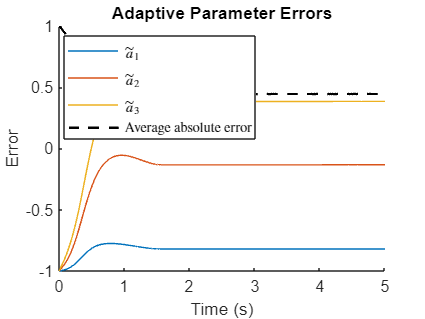


ar_hats = x_ar(:,2*nJoints+1:end);
figure()
hold on
plot(t_ar,ar_hats-a_nums')
plot(t_ar,mean(abs(ar_hats-a_nums'),2),'k--','LineWidth',1.5)
legend("$$\tilde{a}_1$$","$$\tilde{a}_2$$","$$\tilde{a}_3$$","Average absolute error","Location","best","interpreter","latex")
title("Adaptive Parameter Errors")
xlabel("Time (s)")
ylabel("Error")

dt = .05;
qFull = x_ar(:,1:nJoints)';
qFull = qFull(:,1:5:end);
% animate_traj(robot,qFull,dt)
% animate_traj2gif(robot,qFull,dt,'final_traj.gif')